# Invariant prep file 

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 27/07/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Needed Data: **

#### ASSET Px_Last

"DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat"

#### Signal Px_Last

"DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat"

## **Purpose**

**To be able to apply the HS-FP models of Meucci, data needs to be invariants which require IID and somewhat normally distrubuted data.** We use **log difference returns **for equity assets to make them continous and more invariant. For cash we need to transform the forward rate into an invariant. We first show that the initial Price data is not appropriate as invariants, then we transform the data into log diff returns and show that using QQ plots that the invariants are approximately normal and use lagged scatter plots to visually inspect IID datal. 

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));
% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Manipulation/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

**Set Directories & Load Data**

Load Processed Signal and Asset Class data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
load 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';

% Extract the market and cash columns
columnsToExtract = {'JIBA3M_Index','JALSHTR_Index'};
Mrkt_CashTT = SIG_aligned_dataTable(:, columnsToExtract);
% Combine the timetables
BALFUN_TT = synchronize(ASSETCL_TableFilled,Mrkt_CashTT);

Here we see that it's only missing data at the start and not inbetween. 

Create plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(BALFUN_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(ASSETCL_PlotNames, 'TR', '');

**Remove NA:** 

We currently have 23 yrs of data, however, 15 yrs of historical data should suffice, therefore we can drop the dates prior to the initial existance of all indices:

[countNans,idx] = max(sum(isnan(BALFUN_TT{:,:}),1));
rmmissingProxy =  BALFUN_TT.Properties.VariableNames{idx};
BALFUN_TT = rmmissing(BALFUN_TT,"DataVariables",rmmissingProxy);
% spy(transpose(isnan(table2array(BALFUN_TT))))

## 3. Invariant Prep

### 3.1 *** Remove JIBA3M as a forward rate needs to be calculated ***

BALFUN_TT_array = table2array(BALFUN_TT);
JIBA3M = BALFUN_TT.JIBA3M_Index;
BALFUN_TT = removevars(BALFUN_TT, 'JIBA3M_Index');

BALFUN_TT.Properties.Description = 'Monthly Sampled Simple Returns';

### 3.2 JIBA Monthly Rate 

JIBA3M is quoted as an annualised values, therefore we first need to convert it to Quarterly as its a 3 month instrument before converting it to monthly to get cash returns proxy

$\textrm{CI}={\left(1+r\right)}^{\frac{1}{N}} -1,$ where CI is the compounded interest, r is the rate of returns and N is the frequency of interest compounding.

[m,~]=size(BALFUN_TT); % size of TT
% Convert percentage reported value to decimal
JIBA3M_deci = JIBA3M/100;
% Storage for Quarterly and Monthly values
JIBA_q = zeros(m, 1);
JIBA_m = zeros(m, 1);

for t=1:m-1
    % 1. Compute QUARTERLY rate from Annual reported rate
    JIBA_q(t) = ((1+JIBA3M_deci(t,:))^(1/4))-1;
    % 2. Compute MONTHLY expected returns from quarterly
    JIBA_m(t+1) = (((1+JIBA_q(t,:))^(1/3))-1);
end
% Adding it back to the initial dataset to plot it with the price data
BALFUN_TT.Cash = JIBA_m;

### 3.3 Check for normal distribution of PRICE Data

#### 3.3.1 PP Theoritical Distribution Plot

Plot PP and QQ-plots to see confirm that price data is not normally distributed

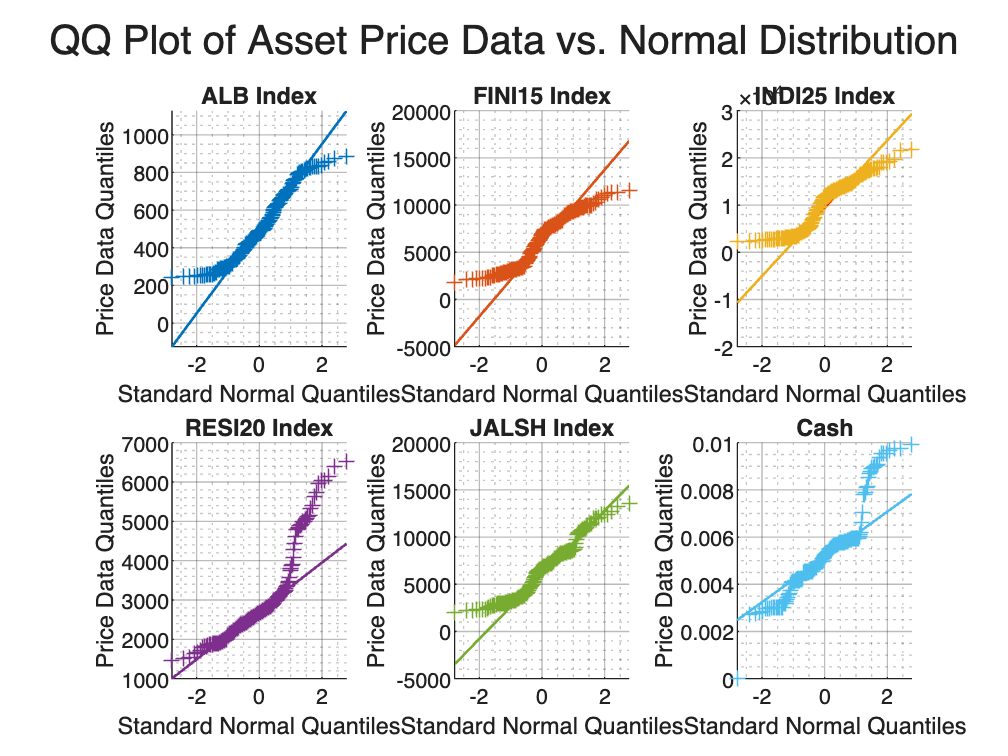

%rename the variables with underscores instead of spaces
BALFUN_TT_PlotNames = strrep(BALFUN_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_TT_PlotNames = strrep(BALFUN_TT_PlotNames, 'TR', '');

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330]; % light blue

% for k = (width(M_Ret_TT)+1):numel(qq)
%     qq(k).LineStyle = "-";
%     qq(k).LineWidth = 1;
% end

% Create a new figure for the plot
% figure('InnerPosition', [100, 100, 600, 600]);
fig = figure;

% Assuming M_Ret_TT is your timetable
numCols = width(BALFUN_TT);
numRows = ceil(numCols / 3);

for col = 1:numCols
    subplot(numRows, 3, col);
    pd = fitdist(BALFUN_TT{:, col},'Normal');
    qq = qqplot(BALFUN_TT{:, col}); % 'normal' is used instead of pd
    % Use colormaps to assign different colors to each line
    qq(3).LineStyle = "-";
    qq(3).Color = [colours(col,:)];
    qq(3).LineWidth = 1;
    qq(1).MarkerEdgeColor = [colours(col,:)];
    
    ylabel("Price Data Quantiles")
    title(BALFUN_TT_PlotNames{col});
    grid on;

    % Adjust grid line properties
    grid(gca, 'minor');
    ax = gca;
    ax.GridAlpha = 0.3; % Set grid transparency
    ax.MinorGridAlpha = 0.25; % Set minor grid transparency
end

qq_plot_prices = fig;

sgtitle("QQ Plot of Asset Price Data vs. Normal Distribution");

**Export QQ plot of ASSET Class log diff returns**

exportName = 'qq_plot_prices.pdf';
exportgraphics(qq_plot_prices, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

#### 3.3.2 Check log diff returns are IID 

Need to be IID to be able to use as a invariant in HS-FP. Plot a scatter plot of the variable vs its own lag. Need to see the points are random and resemble roughly a circle 

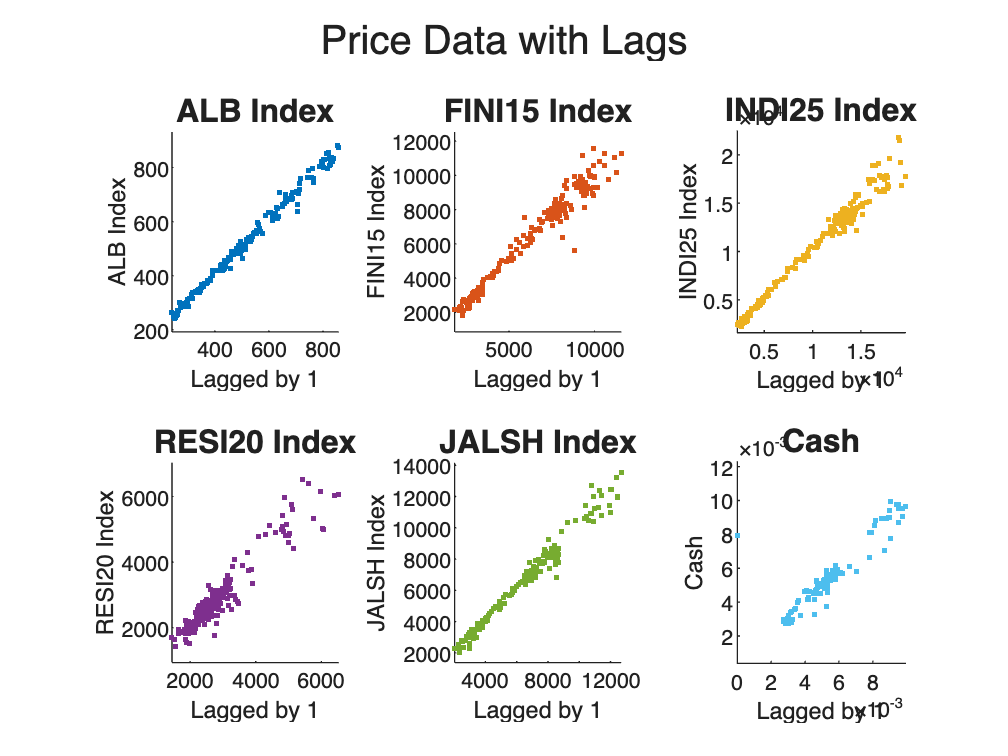

%Get the variable names 
varNames = BALFUN_TT.Properties.VariableNames;

% Create fig
figure;
% plot grid 
numRows = 2;
numCols = 3;

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330]; % light blue

% Loop over each variable
for i = 1:length(varNames)
    % Get the current and lagged version
    current_var = BALFUN_TT.(varNames{i});
    current_lag = lagmatrix(current_var, 2);
    
    % Create scatter plot of current_var and current_lag
    subplot(numRows, numCols, i);
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', colours(i,:), ...
        'MarkerFaceColor', colours(i,:));
    
    % Set the title & axis labels of subplots
    title(BALFUN_TT_PlotNames{i},"FontSize",12);
    ylabel(BALFUN_TT_PlotNames{i});
    xlabel("Lagged by 1");

    % Make the x, y axes equal in length
    axis equal;
end
sgtitle("Price Data with Lags");
% subplot(2,3,1)
% xlim([-0.094 0.089])
% ylim([-0.103 0.115])
% subplot(2,3,2)
% xlim([-0.26 0.23])
% ylim([-0.29 0.30])
% subplot(2,3,3)
% xlim([-0.135 0.133])
% ylim([-0.159 0.163])
% subplot(2,3,4)
% xlim([-0.23 0.22])
% ylim([-0.26 0.28])
% subplot(2,3,5)
% xlim([-0.140 0.132])
% ylim([-0.152 0.175])
% subplot(2,3,6)
% xlim([0.0023 0.0094])
% ylim([0.0014 0.0100])
% Export the fig as a PDF
Price_Lag_Scatterplot = gcf;
hold off

#### **Export Returns Lag scatters Plot**

exportName = 'Price_Lag_Scatterplot.pdf';
exportgraphics(Price_Lag_Scatterplot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 3.4.a CREATE INVARIANTS: Cash invariant 

JIBA Invariant calc (ratio of monthly values) see* Meucci (2007) Risk & Asset Allocation pg 109-114*

% Get the number of columns in the timetable
[m,n]=size(JIBA_m(2:end)); % size of TT
% Returns (include zero or nan for the start)
Ret = zeros(m,1);

% Preallocate arrays for monthly returns and geometric return series
M_Invariant_TT = timetable('RowTimes', BALFUN_TT.Dates(1:end));
cash_relative = timetable('RowTimes', BALFUN_TT.Dates);

for col = 1:n 
    %%% APPROACH 1
    % Get the price data (column) for the current variable
    prices = JIBA_m(2:end);
    for t=1:m-1
        % 1. Computer returns (asset returns)
        Ret(t+1,:) = prices(t+1,:)./prices(t,:);
    end

    cash_relative = Ret;
end
cash_relative = cash_relative(2:end);

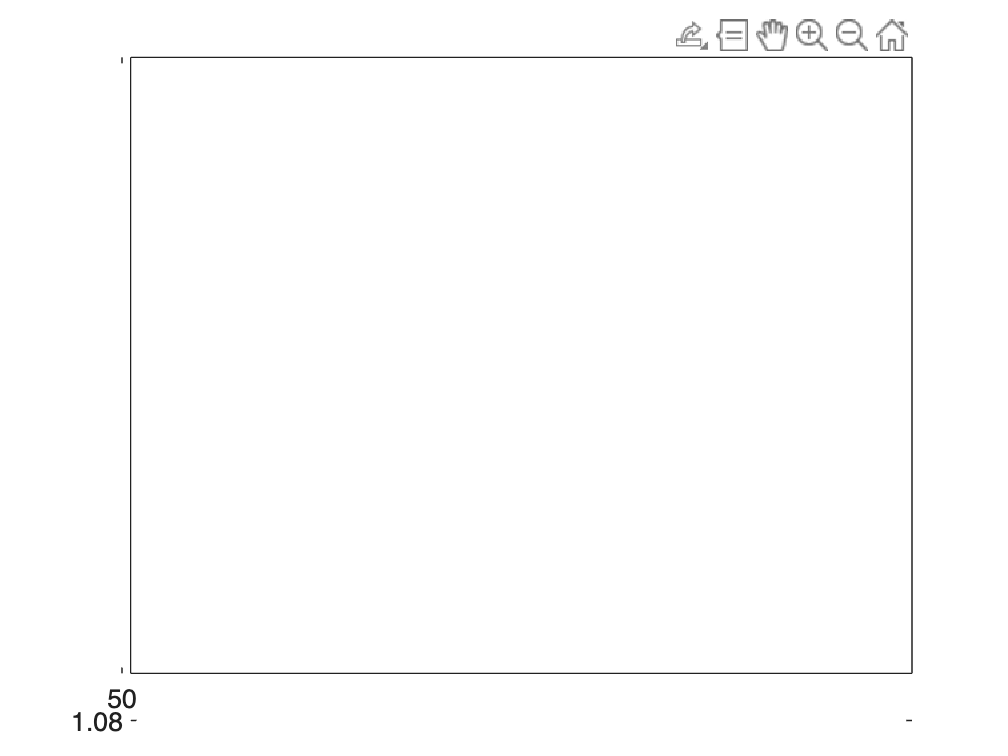

plot(cash_relative)

### 3.4.b CREATE INVARIANTS: Continuous (log dif) returns for all none cash assets

%***************************************************************************
% Get the number of columns in the timetable
[m,n]=size(BALFUN_TT); % size of TT
% Returns (include zero or nan for the start)
Ret = zeros(m,1);

% Preallocate arrays for monthly returns and geometric return series
M_Invariant_TT = timetable('RowTimes', BALFUN_TT.Dates(1:end));
M_Invariant_TT = timetable('RowTimes', BALFUN_TT.Dates);

for col = 1:n
 
    %%% APPROACH 1
    % Get the price data (column) for the current variable
    prices = BALFUN_TT{:, col};
    for t=1:m-1
        % 1. Computer returns (asset returns)
        Ret(t+1,:) = log(prices(t+1,:)/prices(t,:));
    end

    M_Invariant_TT.(BALFUN_TT.Properties.VariableNames{col}) = Ret;
end
M_Invariant_TT = M_Invariant_TT(3:end,:);

#### Add back the JIBAR interest rate to returns table

%%%%%% Add JIBA monthly rate to M_Ret_TT as cash proxy  %%%%%%
M_Invariant_TT.Cash = cash_relative;

%rename the variables with underscores instead of spaces
M_Ret_TT_PlotNames = strrep(M_Invariant_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
M_Ret_TT_PlotNames = strrep(M_Ret_TT_PlotNames, 'TR', '');

#### **SAVE Returns Datasets:**

**TO DO: Use data_cleaning_001 to auto assign date range to file names (will code later)**


M_Invariant_TT.Properties.Description = 'Asset class Simple RETURNS data (used as invariants) - NB for cash asset, the price ratio is use as invaraint due to none IID returns for cash proxy. Frequency: MONTHLY. Latest Update Jan24. Original Source: Bloomberg. Intended file naming: DATA-PROCESSED-ASSETCL-NVARIANT-M-TTABLE-20070831-20230228.mat';
M_Invariant_TT.Properties.VariableDescriptions = {'ALBI Monthly sampled returns', 'FINI Monthly sampled return',...
    'INDI Monthly sampled return','RESI Monthly sampled return', 'ALSI Monthly sampled return', 'price ratio of the JIBA3M forward rate as Cash Proxy Monthly sampled return'};


## Export Invariant Data Timetable

exportName = 'DATA-PROCESSED-ASSETCL-INVARIANT-M-TTABLE-20070831-20230228.mat';
save(fullfile(dataExportpath,exportName),'M_Invariant_TT');

## 4. Check for normal distribution of log dif continuous returns 

#### 4.1 PP Theoritical Distribution Plot

Plot PP and QQ-plots to see if log diff data is roughly normally distributed

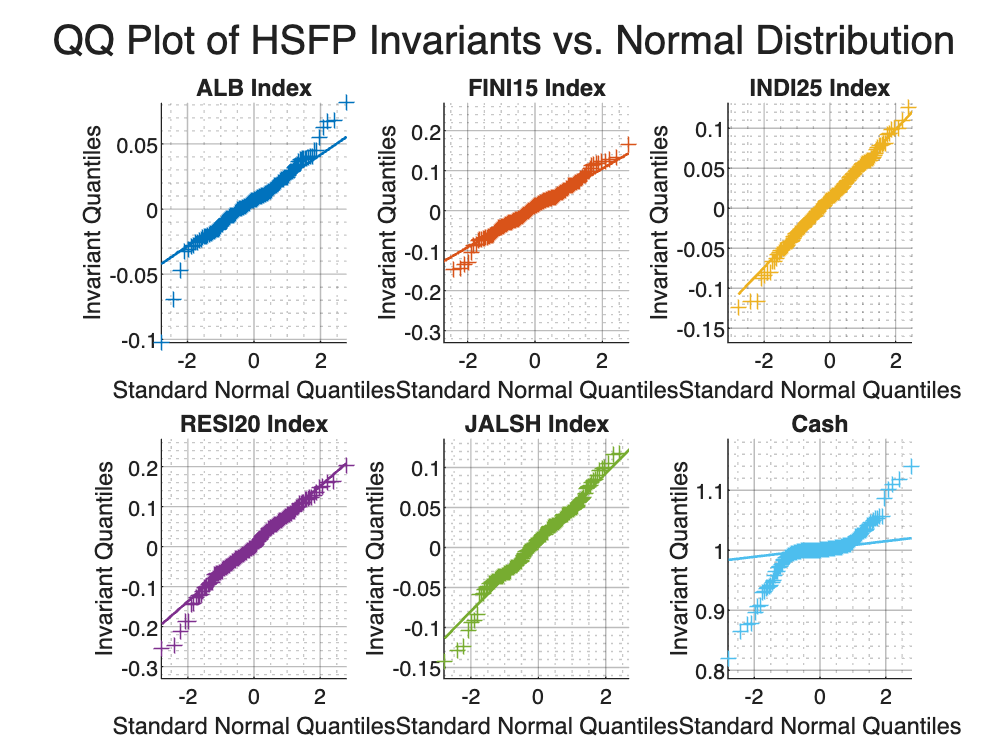

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330]; % light blue

% for k = (width(M_Ret_TT)+1):numel(qq)
%     qq(k).LineStyle = "-";
%     qq(k).LineWidth = 1;
% end

fig = figure;

% Assuming M_Ret_TT is your timetable
numCols = width(M_Invariant_TT);
numRows = ceil(numCols / 3);

for col = 1:numCols
    subplot(numRows, 3, col);
    pd = fitdist(M_Invariant_TT{:, col},'Normal');
    qq = qqplot(M_Invariant_TT{:, col}); % 'normal' is used instead of pd
    % Use colormaps to assign different colors to each line
    qq(3).LineStyle = "-";
    qq(3).Color = [colours(col,:)];
    qq(3).LineWidth = 1;
    qq(1).MarkerEdgeColor = [colours(col,:)];
    
    ylabel("Invariant Quantiles")
    title(M_Ret_TT_PlotNames{col});
    grid on;

    % Adjust grid line properties
    grid(gca, 'minor');
    ax = gca;
    ax.GridAlpha = 0.3; % Set grid transparency
    ax.MinorGridAlpha = 0.25; % Set minor grid transparency
end

qq_plot_invariants = fig;

sgtitle("QQ Plot of HSFP Invariants vs. Normal Distribution");

subplot(2,3,2)
xlim([-2.7 2.8])
ylim([-0.33 0.27])
subplot(2,3,3)
xlim([-3.1 2.5])
ylim([-0.168 0.132])
subplot(2,3,4)
xlim([-2.8 2.8])
ylim([-0.33 0.27])
subplot(2,3,5)
xlim([-2.8 2.7])
ylim([-0.164 0.136])
subplot(2,3,6)
xlim([-2.8 2.8])
ylim([0.786 1.186])

**Export QQ plot of ASSET Class log diff returns**

exportName = 'qq_plot_invariants.pdf';
exportgraphics(qq_plot_invariants, ...
    fullfile(imageExportpath,exportName),'Resolution',300);


#### 4.2 Check log diff returns are IID 

Need to be IID to be able to use as a invariant in HS-FP. Plot a scatter plot of the variable vs its own lag. Need to see the points are random and resemble roughly a circle 

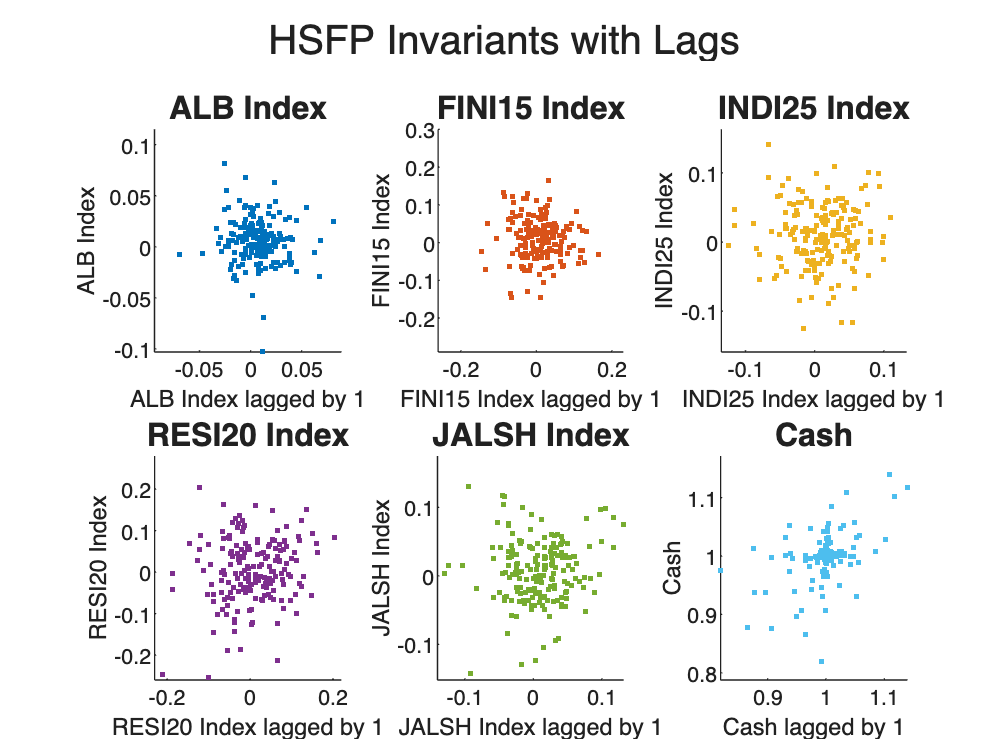

%Get the variable names 
varNames = M_Invariant_TT.Properties.VariableNames;

% Create fig
figure;
% plot grid 
numRows = 2;
numCols = 3;

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330]; % light blue

% Loop over each variable
for i = 1:length(varNames)
    % Get the current and lagged version
    current_var = M_Invariant_TT.(varNames{i});
    current_lag = lagmatrix(current_var, 2);
    
    % Create scatter plot of current_var and current_lag
    subplot(numRows, numCols, i);
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', colours(i,:), ...
        'MarkerFaceColor', colours(i,:));
    
    % Set the title & axis labels of subplots
    title(M_Ret_TT_PlotNames{i},'FontSize',12);
    ylabel(M_Ret_TT_PlotNames{i});
    xlabel(strcat(M_Ret_TT_PlotNames{i}, " lagged by 1"));

    % Make the x, y axes equal in length
    axis equal;
end
sgtitle("HSFP Invariants with Lags");
subplot(2,3,1)
xlim([-0.094 0.089])
ylim([-0.103 0.115])
subplot(2,3,2)
xlim([-0.26 0.23])
ylim([-0.29 0.30])
subplot(2,3,3)
xlim([-0.135 0.133])
ylim([-0.159 0.163])
subplot(2,3,4)
xlim([-0.23 0.22])
ylim([-0.26 0.28])
subplot(2,3,5)
xlim([-0.140 0.132])
ylim([-0.152 0.175])
% subplot(2,3,6)
% xlim([0.0023 0.0094])
% ylim([0.0014 0.0100])
% Export the fig as a PDF
INVARIANT_Lag_Scatterplot = gcf;
hold off

% close all

#### **Export Returns Lag scatters Plot**

exportName = 'INVARIANT_Lag_Scatterplot.pdf';
exportgraphics(INVARIANT_Lag_Scatterplot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

## 5. Plot all results  

### 5.1 Old simple returns version

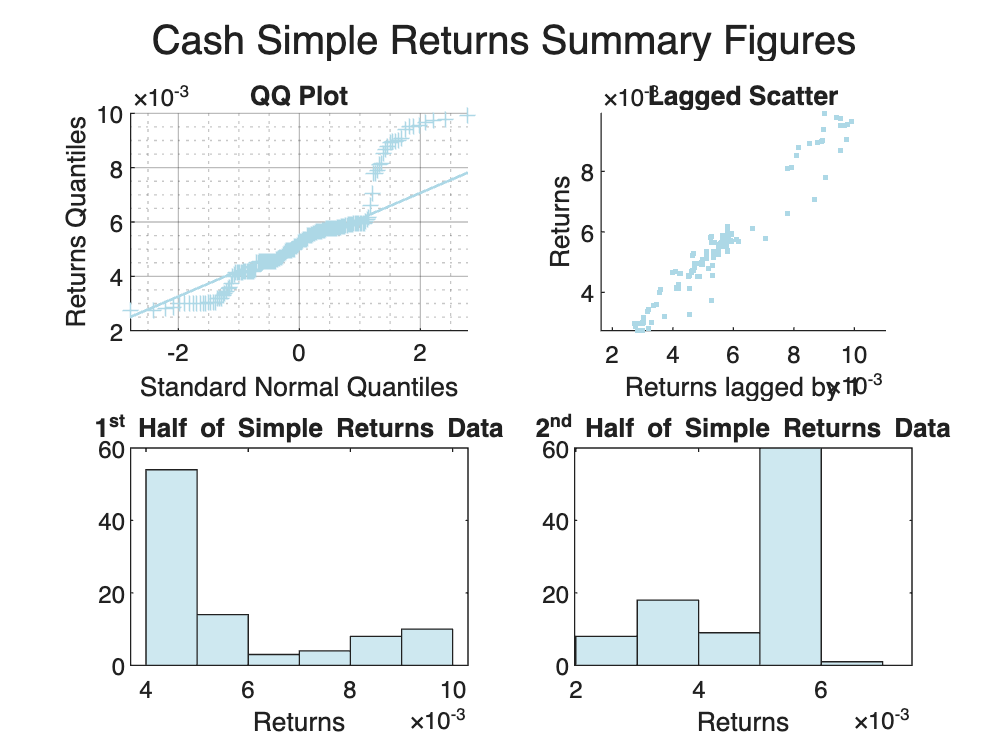

fig = figure;

% Assuming M_Ret_TT is your timetable
numCols = 2;
numRows = 2;

%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(numCols,numRows,1);
    qq = qqplot(JIBA_m(2:end)); % 'normal' is used instead of pd
    % Use colormaps to assign different colors to each line
    qq(3).LineStyle = "-";
    qq(3).Color = [173, 216, 230] / 255;
    qq(3).LineWidth = 1;
    qq(1).MarkerEdgeColor = [173, 216, 230] / 255;
    ylabel("Returns Quantiles");
    title("QQ Plot");
    grid on;

    % Adjust grid line properties
    grid(gca, 'minor');
    ax = gca;
    ax.GridAlpha = 0.3; % Set grid transparency
    ax.MinorGridAlpha = 0.25; % Set minor grid transparency

%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Get the current and lagged version
    current_var = JIBA_m(2:end);
    current_lag = lagmatrix(current_var, 2);
    subplot(numCols,numRows,2);
     
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', [173, 216, 230] / 255, ...
        'MarkerFaceColor', [173, 216, 230] / 255);
    
    % Set the title & axis labels of subplots
    title("Lagged Scatter");
    ylabel("Returns");
    xlabel("Returns lagged by 1");

    % Make the x, y axes equal in length
    axis equal;
%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 3 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    half_point = round((length(JIBA_m)-1)/2); % remove initial 0 value
    subplot(numCols,numRows,3);
    %% Could plot histogram of returns if wanted:
    histogram(JIBA_m(2:half_point), 'FaceColor', [173, 216, 230] / 255)
    title("1^{st} Half of Simple Returns Data")
    % include the legend
    xlabel("Returns")

%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 4 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
    subplot(numCols,numRows,4);
    %% Could plot histogram of returns if wanted:
    histogram(JIBA_m(half_point:end), 'FaceColor', [173, 216, 230] / 255)
    title("2^{nd} Half of Simple Returns Data")
    % include the legend
    xlabel("Returns")
       

cash_simple_comparison_plots = fig;

sgtitle("Cash Simple Returns Summary Figures");

subplot(2,2,4)
xlim([0.00198 0.00748])
ylim([-0 60])

#### **Export cash_simple_comparison_plots **

exportName = 'cash_simple_comparison_plots.pdf';
exportgraphics(cash_simple_comparison_plots, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 5.2 New invariant version

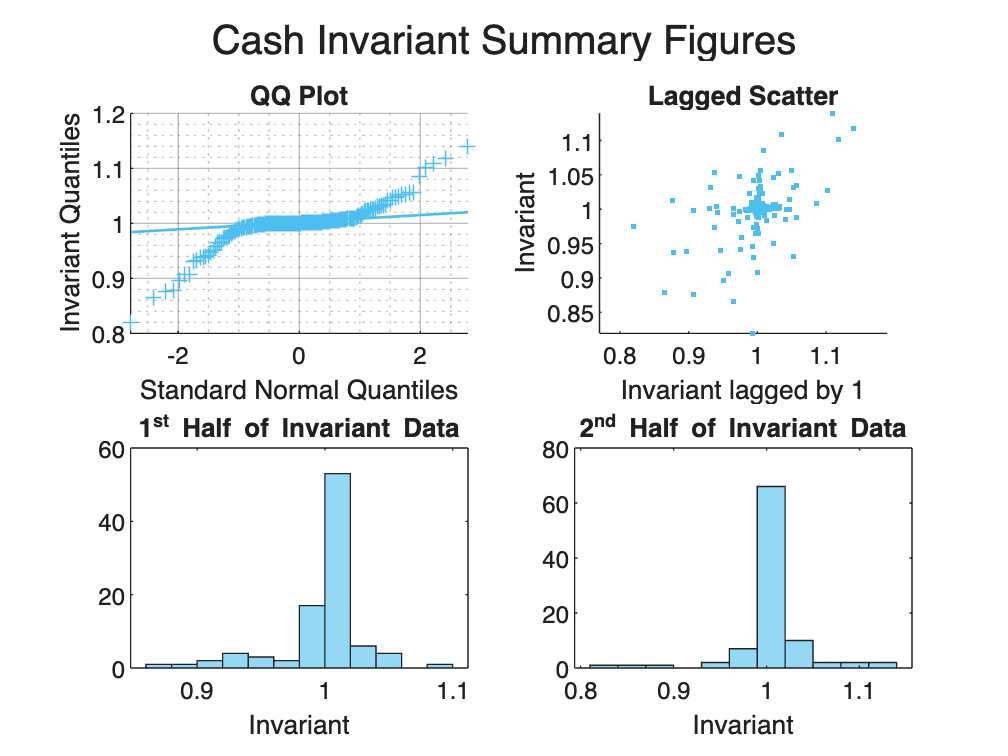

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330]; % light blue

fig = figure;

% Assuming M_Ret_TT is your timetable
numCols = 2;
numRows = 2;

%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(numCols,numRows,1);
    qq = qqplot(cash_relative); % 'normal' is used instead of pd
    % Use colormaps to assign different colors to each line
    qq(3).LineStyle = "-";
    qq(3).Color = [0.3010 0.7450 0.9330];
    qq(3).LineWidth = 1;
    qq(1).MarkerEdgeColor = [0.3010 0.7450 0.9330];
    ylabel("Invariant Quantiles");
    title("QQ Plot");
    grid on;

    % Adjust grid line properties
    grid(gca, 'minor');
    ax = gca;
    ax.GridAlpha = 0.3; % Set grid transparency
    ax.MinorGridAlpha = 0.25; % Set minor grid transparency

%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Get the current and lagged version
    current_var = cash_relative;
    current_lag = lagmatrix(current_var, 2);
    subplot(numCols,numRows,2);
     
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', [0.3010 0.7450 0.9330], ...
        'MarkerFaceColor', [0.3010 0.7450 0.9330]);
    
    % Set the title & axis labels of subplots
    title("Lagged Scatter");
    ylabel("Invariant");
    xlabel("Invariant lagged by 1");

    % Make the x, y axes equal in length
    axis equal;
%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 3 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    half_point = round(length(cash_relative)/2);
    subplot(numCols,numRows,3);
    %% Could plot histogram of returns if wanted:
    histogram(cash_relative(1:half_point), 'FaceColor', [0.3010 0.7450 0.9330])
    title("1^{st} Half of Invariant Data")
    % include the legend
    xlabel("Invariant")

%%%%%%%%%%%%%%%%%%%%%  SUBPLOT 4 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  
    subplot(numCols,numRows,4);
    %% Could plot histogram of returns if wanted:
    histogram(cash_relative(half_point:end), 'FaceColor', [0.3010 0.7450 0.9330])
    title("2^{nd} Half of Invariant Data")
    % include the legend
    xlabel("Invariant")
       
   

cash_invariant_comparison_plots = fig;

sgtitle("Cash Invariant Summary Figures");

#### **Export cash_simple_comparison_plots **

exportName = 'cash_invariant_comparison_plots.pdf';
exportgraphics(cash_invariant_comparison_plots, ...
    fullfile(imageExportpath,exportName),'Resolution',300);